clear ; clc ; close all

## **Specifing the filenames of the audio files**

Audios = ["Short_BBCArabic2.wav", "Short_FM9090.wav", "Short_QuranPalestine.wav", "Short_RussianVoice.wav", "Short_SkyNewsArabia.wav"];                      % names of audio files

## **Obtaining maximum length**

% Initialize variables to store maximum length and corresponding filename

max_audio_length = 0;

% Loop through each audio
for i = 1:length(Audios) % i = 1:5
    % Read the audio file and obtain the audio data
    audio_signal = audioread(Audios{i});
    
    % Calculate the length of the audio file (total number of samples)
    audio_length = size(audio_signal, 1); %% '1' refers to one channel( one coloumn )
    
    % Check if this audio file has the maximum length so far
    if audio_length > max_audio_length
        max_audio_length = audio_length;
    end
end

## **Padding and Monoizing Audios**

for i = 1 : length(Audios)
    
% Read the audio file and obtain the audio data
[audio_signal, Fs] = audioread(Audios{i});  % getting audio data and sampling frequency
audio_signal = sum(audio_signal, 2) / size(audio_signal, 2); % [2]Convert from stereo to mono ( The sum function adds the two channels & The size function determines the number of channels)

% Padding short signals 
audio_signal(end + max_audio_length - length(audio_signal)) = 0; % [3]short channels will be padded with zeros at the last remaining samples of its length after subtracting from maximum length

audiowrite(Audios{i}, audio_signal, Fs);     % save the padded monoized audio signals 
end

## **FFT Of Desired Audio At The Beginning**

fprintf("Choose one of these channels:\n1. Short_BBCArabic2\n2. Short_FM9090\n3. Short_QuranPalestine\n4. Short_RussianVoice\n5. Short_SkyNewsArabia\n");

Choose one of these channels:
1. Short_BBCArabic2
2. Short_FM9090
3. Short_QuranPalestine
4. Short_RussianVoice
5. Short_SkyNewsArabia



choose_channel = input("Choose channel: "); 

    [audio_signal, Fs] = audioread(Audios(choose_channel));  % Read audio and get sampling frequency
    
    Fs  % [1] display sampling freq to use in hand calculations

Fs = 44100

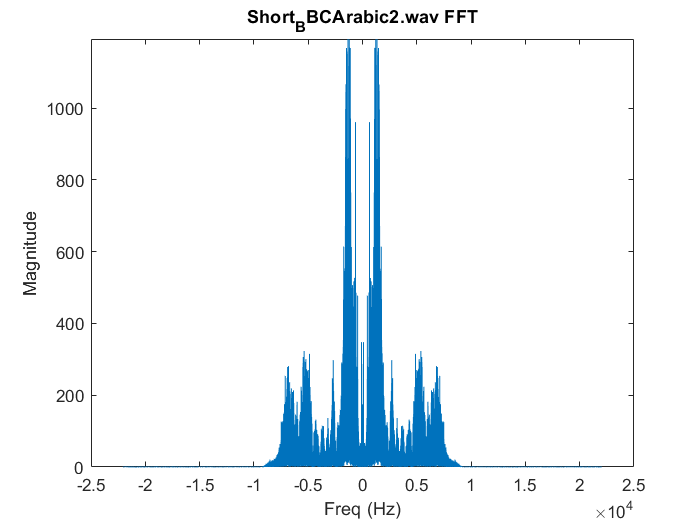

    
    AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal))); %% to be symmetric around 0 (has mathmatical meaning)
    Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)'; % adjust frequency axis (we converted it from row to column by (') because we next will divide it by the AUDIO_SIGNAL array which is a column array and dividing amd multiplying must be in same type)
    
    F= Frequency_vector*Fs/length(AUDIO_SIGNAL); % [4]Freq axis ( freq limits [-Fs/2 ---> Fs/2]  exceeding this range will cause frequencies to fold back )
    
    plot(F, abs(AUDIO_SIGNAL)) % [5] plotting FFT 
    title(Audios(choose_channel) + " FFT")
    xlabel("Freq (Hz)")
    ylabel("Magnitude")
    ylim([0 max(abs(AUDIO_SIGNAL))])

## **Obtaining BandWidth**

    N = length(AUDIO_SIGNAL);

    [pks, freqs] = findpeaks(abs(AUDIO_SIGNAL(1:N/2)), F(1:N/2), 'MinPeakHeight', 0.001*max(abs(AUDIO_SIGNAL(1:N/2)))); % save frequencies and corresponding peaks which achieve the threshold(0.001*max) in two different arrays

    % Compute bandwidth
    bandwidth = max(freqs) - min(freqs);

    disp("bandwidth of " + Audios(choose_channel) + " = " + bandwidth + " Hz"); %[6] BW

bandwidth of Short_BBCArabic2.wav = 9212.3327 Hz


## **Modulating**

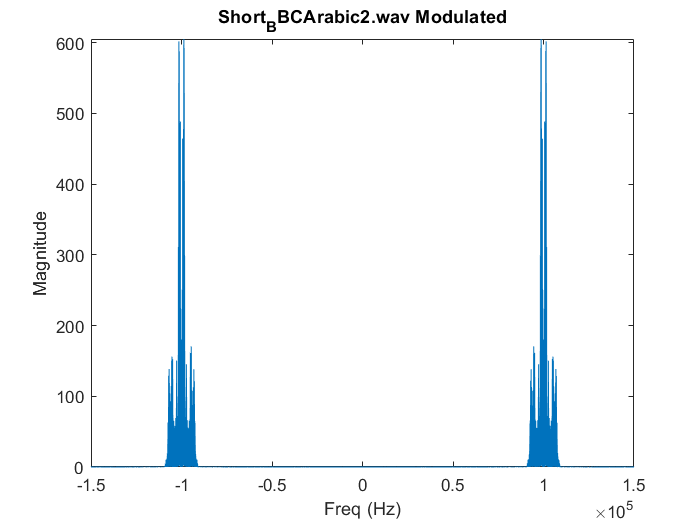

    fo = 100000; 
    n = (choose_channel-1);
    delta_f = 50000;                                    
    fn = fo + n*delta_f;
    
%Fs = 44.1k hz and Fmax(highest freq we reach in whole code) = 2fn(Signal(5))+IF + Bandwidth of signal 5 = 625k +9.11k = 634.11k hz 

%Folding frequencies happens when we reach frequency exceeds Fs/2 and frequencies above that will fold back to lower frequencies

%aliasing happens when folded back frequencies start to interfernce with our signal which centered at 25k hz (after mixer) so we need to increase sampling frequency by multipling Fs by a factor (x) to avoid this 

%F(aliasing) = sampling Freq - Fmax = (x*Fs) - Fmax "should be bigger than 25k + bandwidth of signal 5"

%  x*44.1k - 634.11k > 34.11k  

% x > 15.15 SO -------- x = 16

    audio_signal = (1/16)*interp(audio_signal, 16); %[8] Fs(new)= 16*Fs & length(new) = 16*length & magnitude(new)=16*magnitude so we divided by 16 to not change magnitude
                 
    audio_length = (1:1:length(audio_signal))'; % adjusted to be the same length as our signal
    
    carrier_signal = cos(2*pi*fn*audio_length*(1/(16*Fs)));% [7] carriar signal cos(𝜔𝑛𝑛𝑇𝑆)
   
    modulated_signal = carrier_signal.*audio_signal; % we use (.*) when multiplying arrays

    MODULATED_SIGNAL = fftshift(fft(modulated_signal));
    
    Frequency_vector = (-length(MODULATED_SIGNAL)/2:1:length(MODULATED_SIGNAL)/2-1)';
    
    plot( Frequency_vector*(16*Fs)/length(MODULATED_SIGNAL),abs(MODULATED_SIGNAL) )    
    title( Audios(choose_channel) + " Modulated")
    xlabel("Freq (Hz)")
    ylabel("Magnitude")
    xlim([-1.5*fn 1.5*fn])
    ylim([0 max(abs(MODULATED_SIGNAL))])

  
     bandwidth2 = 2*bandwidth;
     disp("bandwidth of " + Audios(choose_channel) + " Modulated = " + bandwidth2 + " Hz");

bandwidth of Short_BBCArabic2.wav Modulated = 18424.6654 Hz


## **FDM Signal Generation**

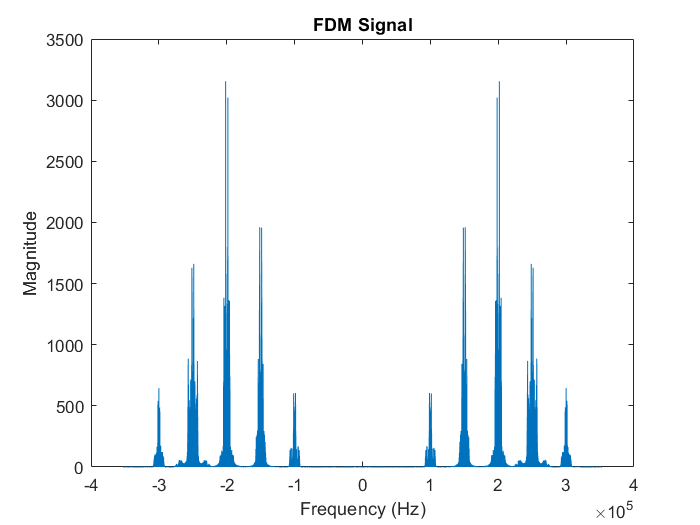

FDM_Signal = 0;  % Frequency Division Multiplixing 

for i = 1 : length(Audios)
    % Read the audio file and obtain the audio data
    [audio_signal, Fs] = audioread(Audios(i));  % Read audio and get sampling frequency

    audio_signal = (1/16)*interp(audio_signal, 16);                              

    fo = 100000;
    n = (i-1);
    delta_f = 50000;                 
                        
    fn = fo + n*delta_f;            
                 
    audio_length = (1:1:length(audio_signal))';
    
    carrier_signal = cos(2*pi*fn*audio_length*(1/(16*Fs)));% [7] carriar signal
   
    modulated_signal = carrier_signal.*audio_signal;
    
    FDM_Signal = FDM_Signal + modulated_signal; %% summing point 
   
end
    FDM_SIGNAL = fftshift(fft(FDM_Signal));
    
    Frequency_vector = (-length(FDM_SIGNAL)/2:length(FDM_SIGNAL)/2-1)';
    
    plot(Frequency_vector*(16*Fs)/length(FDM_SIGNAL),(abs(FDM_SIGNAL)))
    title("FDM Signal")
    xlabel("Frequency (Hz)")
    ylabel("Magnitude")

## **The RF stage**

fprintf("Choose:\n0. Normal operation\n1. Remove RF Filter\n2. 0.1kHz Offset\n3. 1kHz Offset\n");

Choose:
0. Normal operation
1. Remove RF Filter
2. 0.1kHz Offset
3. 1kHz Offset


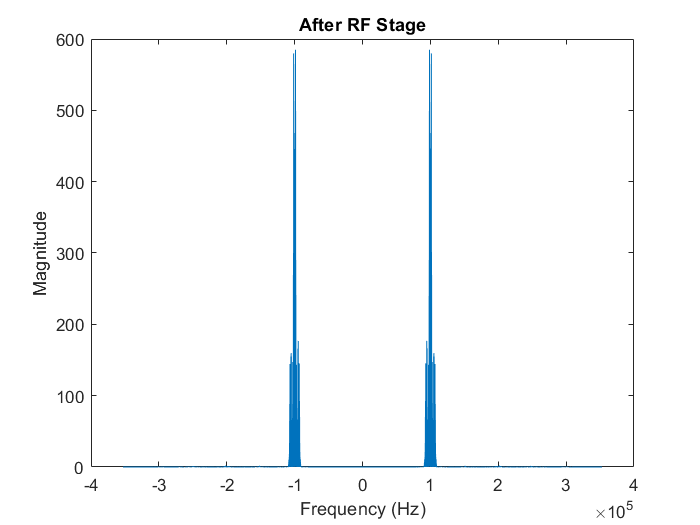


test = input("Choose test: ");
    
if test == 0 || 2 || 3
    
width = 1.2*bandwidth2;                               %width of the RF filter should be bigger than our signal Bandwidth
A_stop1 = 60;                                         % Attenuation in the first stopband = 60 dB
F_stop1 = (choose_channel-1)*50000+100000-27900;      % Edge of the first  stopband = (fn-k) [We choosed maxiumum k that filter can use before interacting with another signal]
F_pass1 = (choose_channel-1)*50000+100000-0.5*width;  % Edge of the first  passband = fn-0.5*width (decreasing F_pass1 to be closer to F_stop1 will increase filter order and make operation slower but give better result & this is not practical)
F_pass2 = (choose_channel-1)*50000+100000+0.5*width;  % Edge of the second passband = fn+0.5*width 
F_stop2 = (choose_channel-1)*50000+100000+27900;      % Edge of the second stopband = (fn+k) making it symmetric is better
A_stop2 = 60;                                         % Attenuation in the second stopband = 60 dB
A_pass = 1;                                           % Amount of ripple allowed in the passband = 1 dB

RF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (16*Fs));
RF_Filter = design(RF_Filter, 'equiripple'); % equiripple is good in dealing with ripples espicially in bandpass filter 
RF_Signal  = filter(RF_Filter, FDM_Signal);
RF_SIGNAL  = fftshift(fft(RF_Signal));
Frequency_vector = (-length(RF_SIGNAL)/2:1:length(RF_SIGNAL)/2-1)';

plot(Frequency_vector*(16*Fs)/length(RF_SIGNAL), abs(RF_SIGNAL))
title("After RF Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")
end

## **Mixer(Oscillator 𝜔𝐶 + 𝜔𝐼f)**

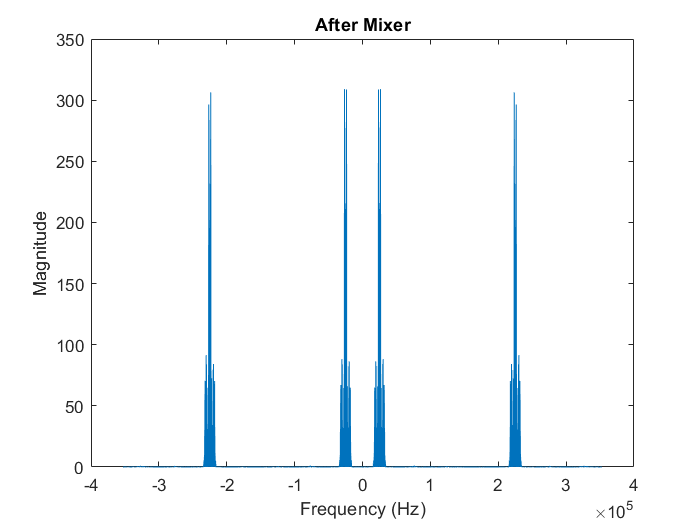

fn = (choose_channel-1)*50000+100000;       % [100, 150, 200, 250, 300] KHz
IF = 25000;                      % If frequency 25 KHz
fLo = fn + IF;   %Local oscillator carrier frequency
if     test == 1
RF_Signal = FDM_Signal;  

elseif test == 2
fLo = fLo + 100;   % 0.1k offset

elseif test == 3
fLo = fLo + 1000;  % 1k offset

else
fLo = fn + IF;
end       

audio_length = (1:1:length(RF_Signal))';

carrier_signal = cos(2*pi*fLo*audio_length*(1/(16*Fs)));

Mixer_Output_Signal = RF_Signal.*carrier_signal;

MIXER_OUTPUT_SIGNAL = fftshift(fft(Mixer_Output_Signal));

Frequency_vector = (-length(MIXER_OUTPUT_SIGNAL)/2:1:length(MIXER_OUTPUT_SIGNAL)/2-1)';

plot(Frequency_vector*(16*Fs)/length(MIXER_OUTPUT_SIGNAL),abs(MIXER_OUTPUT_SIGNAL))
title(" After Mixer ")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

## **IF stage**

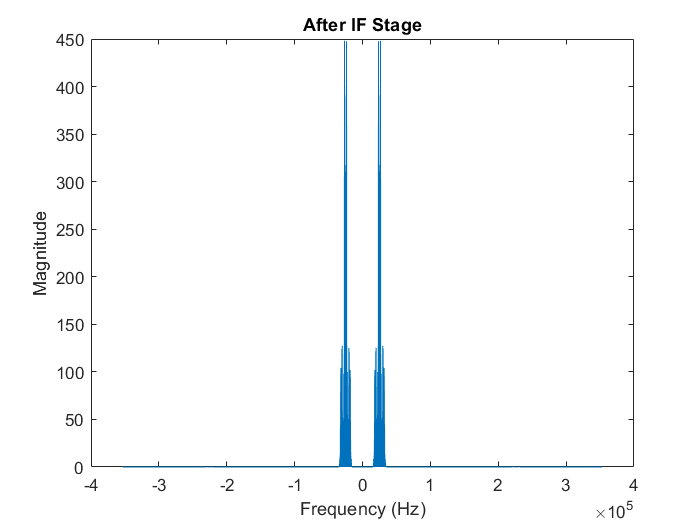

width = bandwidth2;                     % the same as signal bandwidth because of its high selectivity
A_stop1 = 60;                           % Attenuation in the first stopband = 60 dB
F_stop1 = IF-0.5*width-2000;            % Edge of the first  stopband (2000 is used due to available frequency range limitaion)
F_pass1 = IF-0.5*width;                 % Edge of the first  passband
F_pass2 = IF+0.5*width;                 % Edge of the second passband
F_stop2 = IF+0.5*width+2000;            % Edge of the second stopband
A_stop2 = 60;                           % Attenuation in the second stopband = 60 dB
A_pass = 1;                             % Amount of ripple allowed in the passband = 1 dB

IF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (16*Fs));
IF_Filter = design(IF_Filter, 'equiripple');
IF_Signal  = filter(IF_Filter, Mixer_Output_Signal);

IF_Signal = 1.5*IF_Signal; % amplification

IF_SIGNAL  = fftshift(fft(IF_Signal));
Frequency_vector = (-length(IF_SIGNAL)/2:1:length(IF_SIGNAL)/2-1)';

plot(Frequency_vector*(16*Fs)/length(IF_SIGNAL), abs(IF_SIGNAL))
title("After IF Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

## **Base Band Stage (Demodulation)**

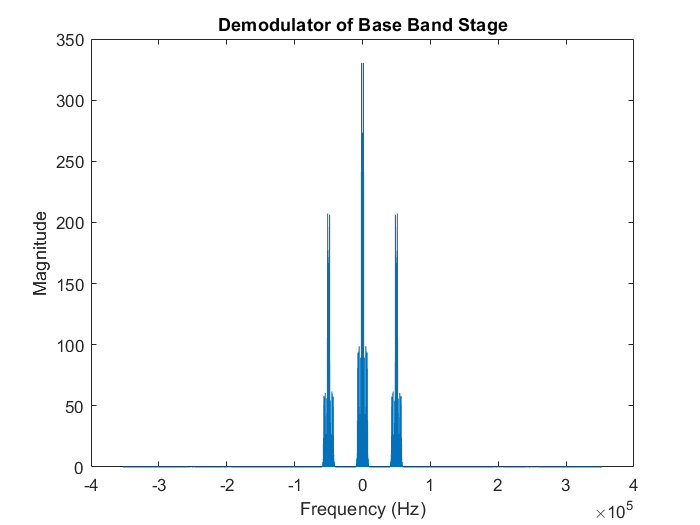

fc = IF;      % BaseBand carrier frequency

audio_length = (1:1:length(IF_Signal))';
carrier_signal = cos(2*pi*fc*audio_length*(1/(16*Fs)));

Base_Band_Signal = IF_Signal.*carrier_signal;
BASE_BAND_SIGNAL = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

plot(Frequency_vector*(16*Fs)/length(BASE_BAND_SIGNAL),abs(BASE_BAND_SIGNAL))
title("Demodulator of Base Band Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

## **The Base Band detection (LPF) **

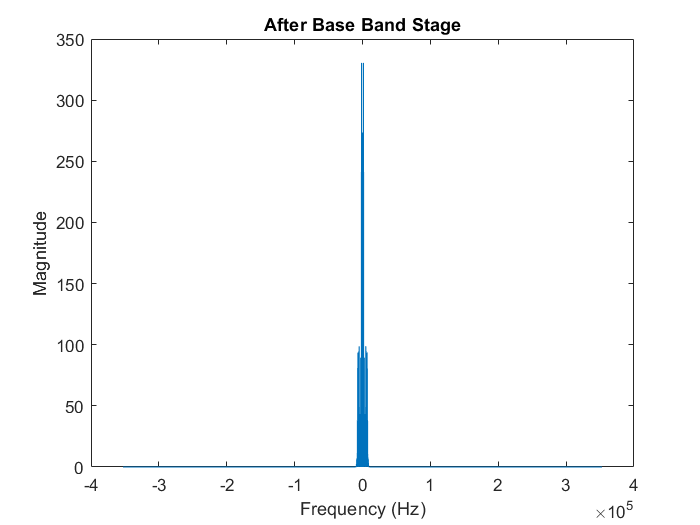

width = bandwidth2;
F_stop = width;              % Edge of the stopband ( we have good available range of frequencies to increase F_stop )
F_pass = width/2;            % Edge of the passband (original bandwidth of the signal)
A_stop = 60;                 % Attenuation in the second stopband = 60 dB
A_pass = 1;                  % Amount of ripple allowed in the passband = 1 dB

Base_Band_Filter= fdesign.lowpass(F_pass, F_stop, A_pass, A_stop, (16*Fs));
Base_Band_Filter = design(Base_Band_Filter, 'butter'); % provide a maximally flat frequency response in the passband, which means they attenuate frequencies uniformly across the passband without any ripples
Base_Band_Signal  = filter(Base_Band_Filter, Base_Band_Signal);
BASE_BAND_SIGNAL  = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';

plot(Frequency_vector*(16*Fs)/length(BASE_BAND_SIGNAL), abs(BASE_BAND_SIGNAL))
title("After Base Band Stage")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

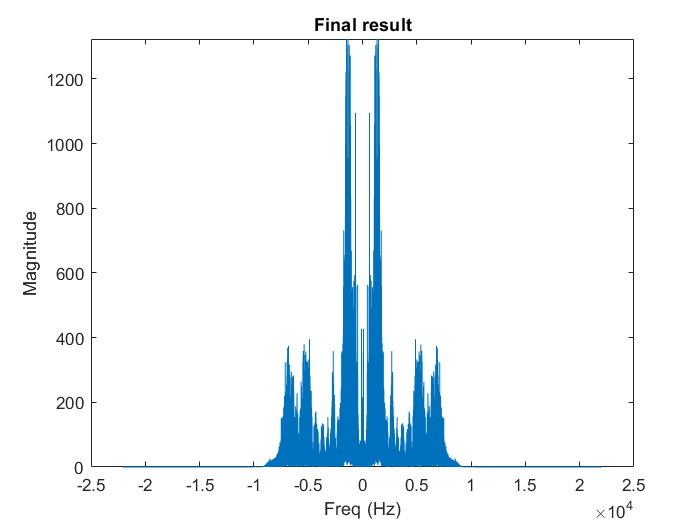


     Base_Band_Signal = 4*16*resample(Base_Band_Signal, 1, 16); %% restore main Fs & length by doing the opposite the interp do & multiplied by 16 because it divides magnitude by 16 and we multiplied by another 4 due to two modulation processses
     
 
     BASE_BAND_SIGNAL  = fftshift(fft(Base_Band_Signal));
    
     Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';
     
     figure
     plot((Frequency_vector*Fs/length(BASE_BAND_SIGNAL)), abs(BASE_BAND_SIGNAL))
     title("Final result")
     xlabel("Freq (Hz)")
     ylabel("Magnitude")
     ylim([0 max(abs(BASE_BAND_SIGNAL))])

     
sound(Base_Band_Signal, Fs)  % to listen to our station

 % --------------------testing different actions to sound-----------------------------

errors = ["Removed_RF.wav", "0.1 KHz Offset.wav", "1 KHz Offset.wav"];% three tests
if test == 0

else 
audiowrite(errors{test}, Base_Band_Signal, Fs);   % save test audios, Test{1} Test{2} Test{3}
end